# **Automated Glaucoma Diagnosis using Deep  Learning Approach**

By - ***Baidaa Al-Bander***

*Architecture****: *****Transfer Leanring **

                     **Pretrained Alexnet as Feature Extractor**

**                     SVM as classifier**

*Preprocessing****: *****Resize image to 227*227**

*DataSet**** : *****RIM-ONE V2**

                **Total Image Count: 455**

**                Normal Images: 255**

*Author:* **Gyanendar Manohar (R00207241)**

*Date:**** 26/02/2022***

***==========================================================================================***

### Set Random Seed

rng(50)

## **Load Dataset **

Load RIM-ONE R2 dataset and split it in train and test set. The split ration is 70:30


image_data_store = imageDatastore('C:\gyani\Projects_MS\code\dataset\RIMONE-db-r2','IncludeSubfolders',true,'LabelSource','foldernames');

[x_train_ds,x_test_ds] = splitEachLabel(image_data_store,0.7,'randomized');

## Alexnet Model

Get pre-trained AlexNet Model

alexnet_model = alexnet

alexnet_model =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


%analyzeNetwork(alexnet_model)

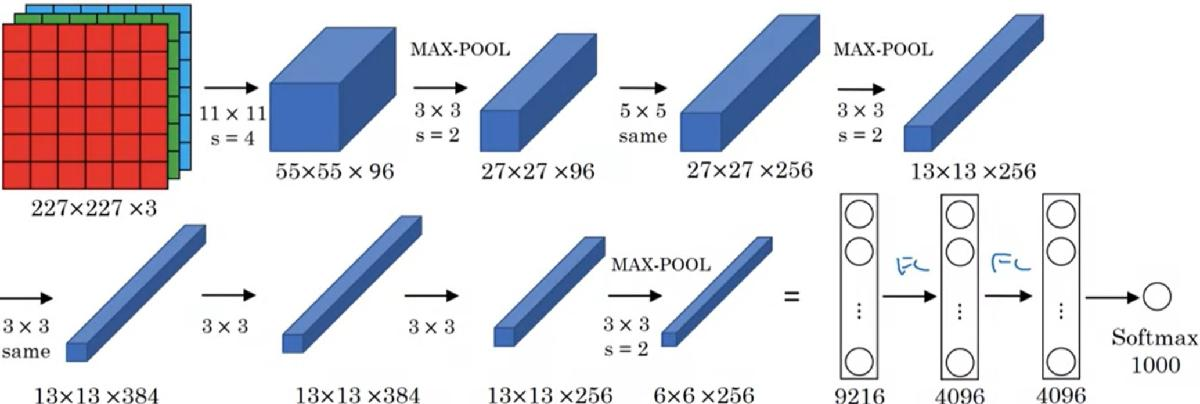

### Model input size

input_Size = alexnet_model.Layers(1).InputSize;

### Resize Image to match the input size

aug_train = augmentedImageDatastore(input_Size(1:2),x_train_ds);
aug_test = augmentedImageDatastore(input_Size(1:2),x_test_ds);

### Train and Test labels

y_train = double(categorical(x_train_ds.Labels));
y_test = double(categorical(x_test_ds.Labels));

### Extract Feature from images

layer = 'relu6';
feature_train = activations(alexnet_model,aug_train,layer,'OutputAs','rows');
feature_test = activations(alexnet_model,aug_test,layer,'OutputAs','rows');

### Pass Extracted features to SVM classifier

classifier = fitcecoc(feature_train,y_train);

# Result

### Do prediction

y_predicted = predict(classifier,feature_test);

### Accuracy

accuracy = mean(y_predicted == y_test)

accuracy = 0.8897

### Confusion Matrix

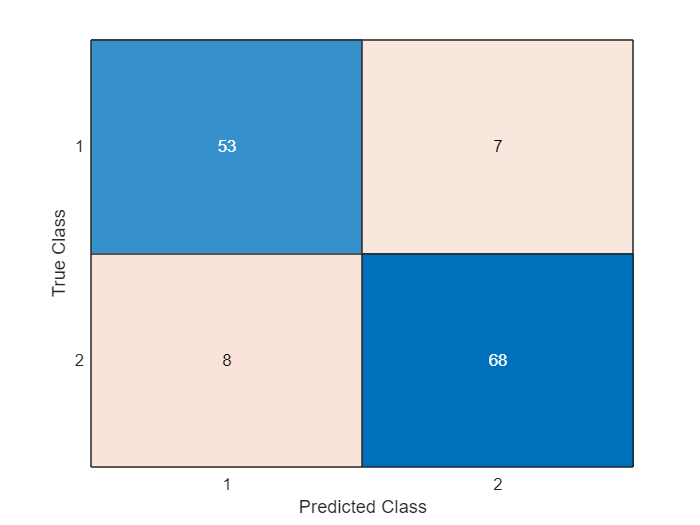

%[c,cm,ind,per] = confusion(y_test,y_predicted)
confusionchart(y_test,y_predicted)


[conf_matrix,order] = confusionmat(y_test,y_predicted)

conf_matrix =     53     7
     8    68


order =      1
     2


tp = conf_matrix(1,1)

tp = 53

tn = conf_matrix(2,2)

tn = 68

fn = conf_matrix(1,2)

fn = 7

fp = conf_matrix(2,1)

fp = 8

### Sensitivity

sensitivity = tp/(tp+fn)

sensitivity = 0.8833

### Specificity

specificity = tn/(tn+fp)

specificity = 0.8947